clear;

syms t theta(t) phi(t) tau(t)
syms g mw mp a l J c_1 c_2

q = [theta(t); phi(t)];
f = [0; tau(t)];
dq = diff(q, t);
ddq = diff(dq, t);

% wheel vel
xw = a * (q(1) + q(2))

$$xw = a\,\left(\varphi \left(t\right)+\theta \left(t\right)\right)$$

vw = diff(xw, t);
% pendulam vel
xp = xw + l * cos(q(1));
yp = -l * sin(q(1));
dx = diff(xp, t);
dy = diff(yp, t);
vp = sqrt(dx^2 + dy^2);

%% wheel energy
% rotation ene
Kwr = (1/2 *  (dq(1) + dq(2)))^2;

% translation ene
Kwt = 1/2 * mw * vw^2;

% potential ene
% zero

%% pendulam energy
% rotation ene
Kpr = 1/2 * J * dq(1)^2;

% translation ene
Kpt = 1/2 * mp * vp^2;

% potential ene

Up = mp * g * l * cos(q(1));

K = Kwr + Kwt + Kpr + Kpt;

% Laglagian
L = K -Up;

% 損失エネルギー
D = [1/2 * c_1 * dq(1)^2, 1/2 * c_2 * dq(2)^2];

運動方程式の導出

% ラグラジアンによる運動方程式の導出
N = length(q);
dLq = sym('dLq', [2 1]);
ddLq = sym('ddLq', [2 1]);
eq = sym('eq', [2 1]);

for i = 1:N
    dLq(i) = diff(L, dq(i));

    temp = 0;
    for j = 1:N
        temp = temp + diff(dLq(i),dq(j)) * ddq(j) + diff(dLq(i),q(j)) * dq(j);
    end
    ddLq(i) = temp;

    eq(i) = ddLq(i)-diff(L, q(i)) == -D(i) + f(i);
end
eq(1)

$$ans = \begin{array}{l} \left(J+a^{2}\,\mathrm{mw}+\frac{\mathrm{mp}\,\left(2\,{\sigma_{2}}^{2}+2\,l^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}\right)}{2}+\frac{1}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\left(a^{2}\,\mathrm{mw}+a\,\mathrm{mp}\,\sigma_{2}+\frac{1}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+\frac{\mathrm{mp}\,\left(2\,l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+2\,l^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{3}\right)}{2}-\frac{\mathrm{mp}\,\left(l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}\,2+4\,l^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+2\,l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}-g\,l\,\mathrm{mp}\,\sin\left(\theta \left(t\right)\right)=-\frac{c_{1}\,\sigma_{3}}{2}\\ \mathrm{where}\\ \sigma_{1}=a\,\left(\frac{\partial }{\partial t}\varphi \left(t\right)+\frac{\partial }{\partial t}\theta \left(t\right)\right)-l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}=a-l\,\sin\left(\theta \left(t\right)\right)\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

eq(2)

$$ans = \left(a^{2}\,\mathrm{mp}+a^{2}\,\mathrm{mw}+\frac{1}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+\left(a^{2}\,\mathrm{mw}+a\,\mathrm{mp}\,\left(a-l\,\sin\left(\theta \left(t\right)\right)\right)+\frac{1}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-a\,l\,\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}=\tau \left(t\right)-\frac{c_{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

シミュレーション

% パラメータ
% t theta(t) phi(t) tau(t)
% g mw mp a l J c_1 c_2

tau = 0;
g = 9.81;
mw =0.1;
mp = 0.5;
a = 0.05;
l = 0.1;
J = 0;
c_1 = 0;
c_2 = 1;

eqn_1 = subs(eq(1));
eqn_2 = subs(eq(2));
[V,State] = odeToVectorField(eqn_1, eqn_2);

solberHandler = matlabFunction(V, 'Vars', {'t', 'Y'})

solberHandler = 値をもつ function_handle :
    @(t,Y)[Y(2);((sin(Y(3)).*9.83943e+5+sin(Y(3)).^2.*Y(2).^2.*1.0e+4+Y(2).^2.*1.003e+6-sin(Y(3)).^2.*4.905e+3-sin(Y(3)).*Y(2).^2.*1.0e+4+cos(Y(3)).^2.*Y(2).^2.*1.0e+4-cos(Y(3)).^3.*Y(4).^2.*5.0e+1-cos(Y(3)).*sin(Y(3)).^2.*Y(4).^2.*5.0e+1+cos(Y(3)).*sin(Y(3)).*Y(4).^2.*2.5e+1).*(-1.0./5.0))./(cos(Y(3)).^2.*2.006e+3+sin(Y(3)).^2.*2.001e+3);Y(4);(sin(Y(3)).*9.83943e+5+Y(2).^2.*1.003e+6-sin(Y(3)).*Y(2).^2.*5.0e+3+cos(Y(3)).*sin(Y(3)).*Y(4).^2.*2.5e+1)./(cos(Y(3)).^2.*1.003e+4+sin(Y(3)).^2.*1.0005e+4)]



initCond = [0.001 0 0.001 0];
TimeLength = [0 20];
sol = ode45(solberHandler, TimeLength, initCond);

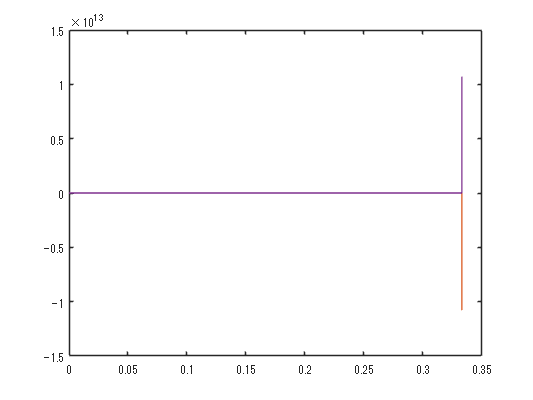


plot(sol.x, sol.y)